## Introduction to Environmental Data Analysis and Statistical Learning 

## Exercise 8 – Kullback-Leibler divergence

#### Ka Hei Pinky, Chow

### Reference Distribution

x = normrnd(0,1,[1000000,1]);
[N, edges] = histcounts(x, 50,'BinLimits',[-10,10]);


### Test distributions

all combinations of mean=(0:0.1:2) and standard deviation=(1:0.1:2)

mu_idx = 1; %set up a mean counter
DKL_matrix = zeros(length(0:0.1:2),length(1:0.1:2)); %set up a zero matrix for filling in the values
all = 1000000; %the data points in both reference and test distribution are 1000000
for mu = 0:0.1:2 %all possibility of mean
    sd_idx = 1; %set up a S.D. counter
    for sd = 1:0.1:2 %all possibility of standard deviation      
        x1 = normrnd(mu,sd,[1000000,1]); %set up values in normal distribution
        [N1, edges1] = histcounts(x1, 50,'BinLimits',[-10,10]); %putting them into the bins

        %Calculating DKL to reference distribution
        DKL_single = 0;
        for i = 1:length(N1)
            if N1(i) ~= 0 && N(i) ~= 0 %excluding scanerios with p(reference) = 0 or p(model) = 0
                DKL_single = DKL_single + (N(i)/all)*log2((N(i)/all)/(N1(i)/all)); %calculating Kullback-Leibler divergence
            else  
            end
        end
        DKL_matrix(mu_idx,sd_idx) = DKL_single; %putting the calculated DKL value in this scanerio to the according cell 
        %of the matrix. The according N1 and edges1 values will be overwritten.
        
        %In the resultant DKL matrix, the rows represnet the values of mean and the 
        %columns represent the values of standard variation.

        sd_idx = sd_idx + 1; %counting the S.D. index number
    end
    mu_idx = mu_idx + 1; %counting the mean index number
end


### Results

disp(DKL_matrix)

  Column 1

    0.0000
    0.0071
    0.0283
    0.0633
    0.1148
    0.1775
    0.2552
    0.3465
    0.4544
    0.5743
    0.7097
    0.8634
    1.0221
    1.2010
    1.3961
    1.6043
    1.8168
    2.0519
    2.3056
    2.5694
    2.8328

  Column 2

    0.0122
    0.0180
    0.0354
    0.0643
    0.1057
    0.1585
    0.2230
    0.3006
    0.3870
    0.4884
    0.6011
    0.7227
    0.8627
    1.0046
    1.1669
    1.3385
    1.5220
    1.7111
    1.9357
    2.1382
    2.3542

  Column 3

    0.0415
    0.0463
    0.0629
    0.0862
    0.1203
    0.1647
    0.2209
    0.2858
    0.3593
    0.4438
    0.5383
    0.6412
    0.7555
    0.8817
    1.0150
    1.1561
    1.3096
    1.4747
    1.6509
    1.8277
    2.0230

  Column 4

    0.0827
    0.0864
    0.0995
    0.1207
    0.1500
    0.1895
    0.2348
    0.2899
    0.3533
    0.4232
    0.5063
    0.5965
    0.6895
    0.7988
    0.9108
    1.0344
    1.1658
    1.3075
    1.4495
    1.6131
    1.7808

  Column 5

    0.1305
 

### Plotting the Mesh Plot

X = standard deviation, Y = mean , Z = DKL value

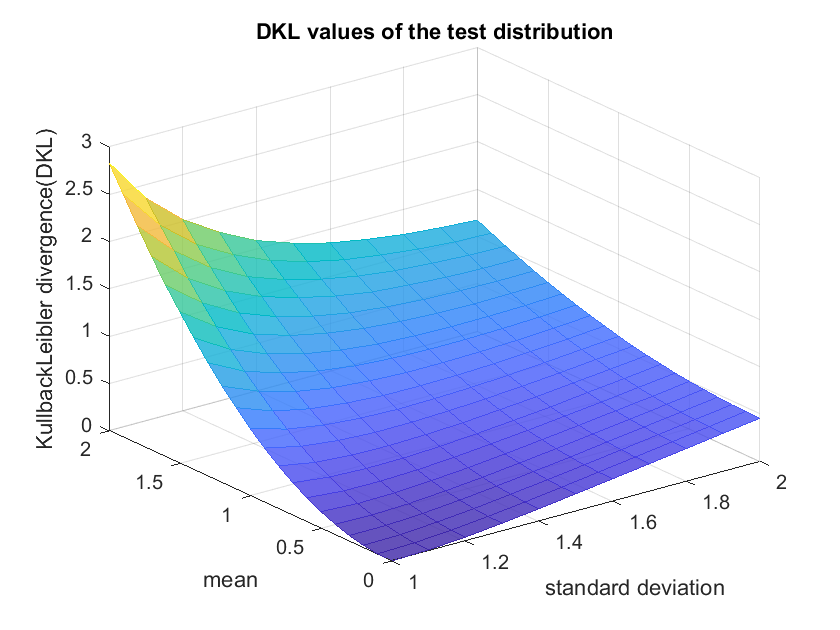

X = 1:0.1:2;
Y = 0:0.1:2;
Z = DKL_matrix;
size(DKL_matrix);
mesh(X,Y,Z,'FaceColor','flat','FaceAlpha','0.8')
xlabel('standard deviation')
ylabel('mean')
zlabel('KullbackLeibler divergence(DKL)')
title('DKL values of the test distribution')

### Discussion

- **Comparison**


%for the test distribution mean = 1, standard deviation = 1,
%DKL value = 
disp('DKL value for the test distribution mean = 1, standard deviation = 1: ') 

DKL value for the test distribution mean = 1, standard deviation = 1: 


DKL_matrix(11,1)

ans = 0.7097


%for the test distribution mean = 0, standard deviation = 2,
%DKL value = 
disp('DKL value for the test distribution mean = 0, standard deviation = 2: ')

DKL value for the test distribution mean = 0, standard deviation = 2: 


DKL_matrix(1,11)

ans = 0.4531

It means the divergence is smaller when the mean is correct in the

model, compared to the divergence value with only standard

deviation being correct. 

- **General Observations**

From what we can observe in the plot, the divergence is 0 when both mean and standard deviation of the model matches the true values. When the standard deviation deviates, the divergence values increases gradually close to a linear tendency. When standard deviation is 2 instead of 1 with correct mean value 0, DKL value rise from 0 to around 0.45. Whereas when the mean deviates, the devergence values increases rather sharply with a tendency close to expotential growth. When mean is 1 instead of 0 with correct standard deviation value 1, the DKL value increases from 0 to around 0.7. 

One interesting observation is the additive effect of the wrong mean and wrong standard deviation. With deviation of mean such as 2, a larger deviation of standard deviation appears to mitigate the sharp increase of DKL value. From testing other means and standard deviations of the "true distribution", we can observed that an increasing standard deviation can generally suppressed the DKL value. Therefore, a too-large standard deviation has less impact on DKL value compared to a too-small standard deviation in our model. Yet, the effect of wrong standard deviation on DKL value is still less than the effect of wrong mean. 

From the observation, we can consider the truthness of mean as a more crucial factor for the gain of information and suppression of uncertainty. The accuracy of standard deviation is not as important in comparison. It is, hence, **more important to have good estimate of true mean to minimize DKL with our model**.